# B3シミュレーション

## 送受信システムブロック図

ブロック図をここに貼る

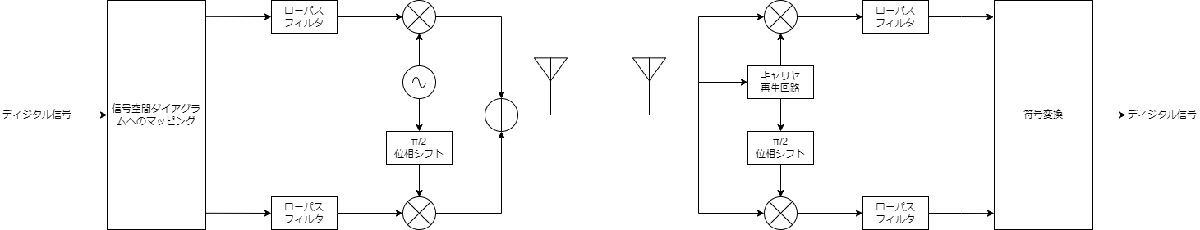

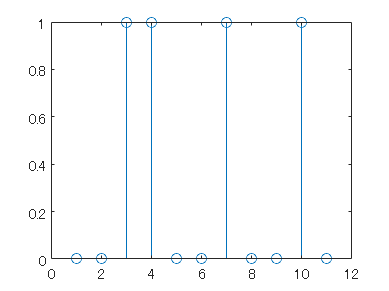

clear;
clc;

fs = 10000; %サンプリング周波数[Hz]
fc = 10; %データレート[Hz]
A = 3; %振幅
TXD = [0 0 1 1 0 0 1 0 0 1 0]; %送信データ
stem(TXD)
t = 0:1/fs:(numel(TXD)-1)/fc; %離散時間[s]

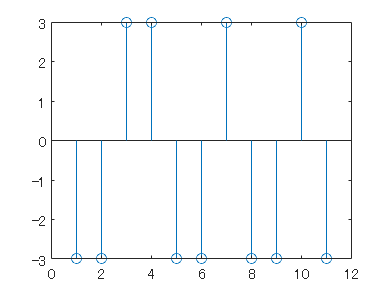


%信号空間ダイアグラムへのマッピング
BPSK(TXD==0) = -A;
BPSK(TXD==1) = A;
stem(BPSK)

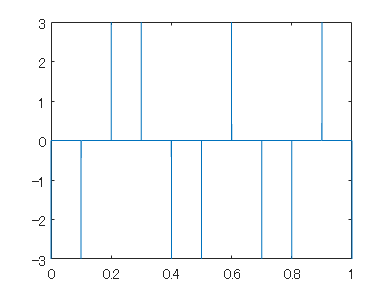


%インパルス列作成
i = 1;
impulse = zeros(1,numel(t));
for data = BPSK
    impulse(i) = data; 
    i = i + fs/fc;
end
plot(t,impulse);